# Import AUTOSAR Adaptive Components to Simulink

Create Simulink® models from XML descriptions of AUTOSAR adaptive software components.

## Import AUTOSAR Adaptive Components from ARXML Files to Simulink

Use the MATLAB function [`createComponentAsModel`](docid:autosar_ref.mw_c5a5ec11-d9aa-4c75-9933-8258099589ea) to import AUTOSAR XML (ARXML) adaptive software component descriptions and create Simulink models.

First, parse the ARXML description files and list the components they contain.

ar = arxml.importer({'fusion_app.arxml','radarService_app_mod.arxml','radar_svc_mod.arxml','stdtypes_mod.arxml'});
names = getComponentNames(ar)

For each listed adaptive software component, use `createComponentAsModel` to create a Simulink representation. These commands create models named `fusion` and `radarService`.

createComponentAsModel(ar,'/RadarFusion/fusion');
createComponentAsModel(ar,'/RadarFusion/radarService');

Each created model contains:

- Simulink elements configured to model AUTOSAR adaptive component elements.

- An AUTOSAR dictionary, which stores the imported AUTOSAR adaptive element definitions.

- A mapping of the Simulink model elements to the AUTOSAR adaptive component elements.

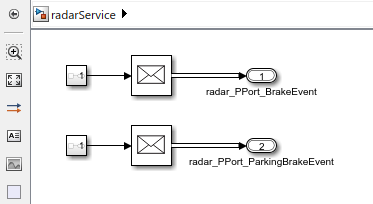

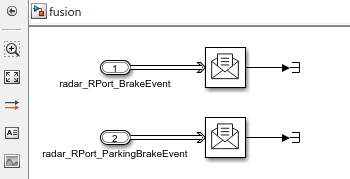

In each model:

- Simulink ports represent AUTOSAR adaptive component provide and require ports.

- After each root inport, an Event Receive block converts an input event to a signal while preserving the signal values and data type.

- Before each root outport, an Event Send block converts an input signal to an event while preserving the signal values and data type.

- The ports are stubbed with Ground and Terminator blocks so that the model can immediately be updated and simulated.

## Configure AUTOSAR Adaptive Software Component in Simulink

After you create an AUTOSAR adaptive software component model, use the **AUTOSAR Component Designer** app to refine the configuration of the AUTOSAR adaptive component.

Open an adaptive component model. On the **Apps** tab, select **AUTOSAR Component Designer**. The **AUTOSAR** tab opens.

To view the mapping of Simulink model elements to AUTOSAR adaptive component elements, open the Code Mappings pane. Use this view to map model elements to AUTOSAR component elements from a Simulink model perspective.

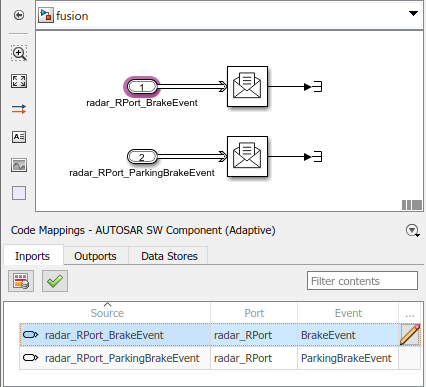

To view AUTOSAR adaptive element definitions, on the **AUTOSAR** tab, select **Code Interface** > **AUTOSAR Dictionary**. The dictionary opens. Use this view to configure AUTOSAR elements from an AUTOSAR component perspective.

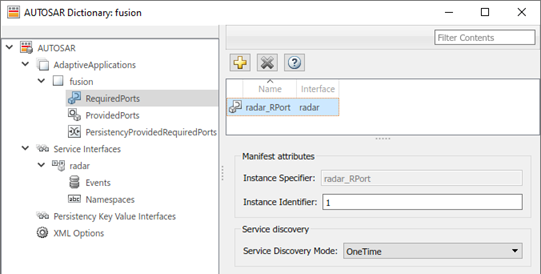

For more information, see [AUTOSAR Component Configuration](docid:autosar_ug.bt2wgsd).

## Develop AUTOSAR Adaptive Component Algorithms, Simulate, and Generate Code

After you create an AUTOSAR adaptive software component model and refine the configuration, you develop the component. Create algorithmic model content that implements the component requirements.

For example, the `fusion` component model that you created contains an initial stub implementation of the component behavior.

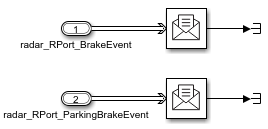

To implement the component requirements, replace the Terminator blocks with blocks that implement Simulink algorithms.

As you develop AUTOSAR adaptive components, you can:

- Simulate the component model individually or in a containing composition or test harness.

- Generate ARXML component description files and algorithmic C++ code for testing in Simulink or integration into an AUTOSAR run-time environment. (AUTOSAR code generation requires Simulink Coder and Embedded Coder.)

For more information, see [AUTOSAR Component Development](docid:autosar_doccenter.mw_840acc5f-725a-4ba4-b410-d9b5c904caed) and [AUTOSAR Code Generation](docid:autosar_doccenter.mw_e655a5c6-8aec-4d28-914b-088b3c4ac00c).

## Related Links

- [`createComponentAsModel`](docid:autosar_ref.mw_c5a5ec11-d9aa-4c75-9933-8258099589ea)

- [AUTOSAR Component Creation](docid:autosar_doccenter.mw_7931a85c-ea35-45bf-b0e9-eccea0ca94a0)

- [AUTOSAR Component Configuration](docid:autosar_ug.bt2wgsd)

- [AUTOSAR Component Development](docid:autosar_doccenter.mw_840acc5f-725a-4ba4-b410-d9b5c904caed)

- [AUTOSAR Code Generation](docid:autosar_doccenter.mw_e655a5c6-8aec-4d28-914b-088b3c4ac00c)

*Copyright 2019 The MathWorks, Inc.*